% Add the functions folder to the matlab path in order 
% to use them
oldpath = path;
path(oldpath,'functions');

% Generate the signal
Fs = 44100;      % Hz
len_sign = 1;  % s

% sinusoids : [freq, phase, amp]
sinusoids = [100     0*2*pi      10;
    200     0*2*pi      10;
    300     0*2*pi      10;
    400     0*2*pi      10;
    500     0*2*pi      10;
    ];
% amplitude of noise
noise_amp = 1;

signal = create_signal(sinusoids, noise_amp, len_sign, Fs);

PATH = 'records/d_string/d4/';
files = dir(strcat(PATH, 'd4_00001.wav'));

file = files;

[signal, Fs] = audioread(strcat(file.folder,'/',file.name));

signal_len = length(signal) / Fs;

[Y, Y_indices] = param_FFT(signal, Fs);

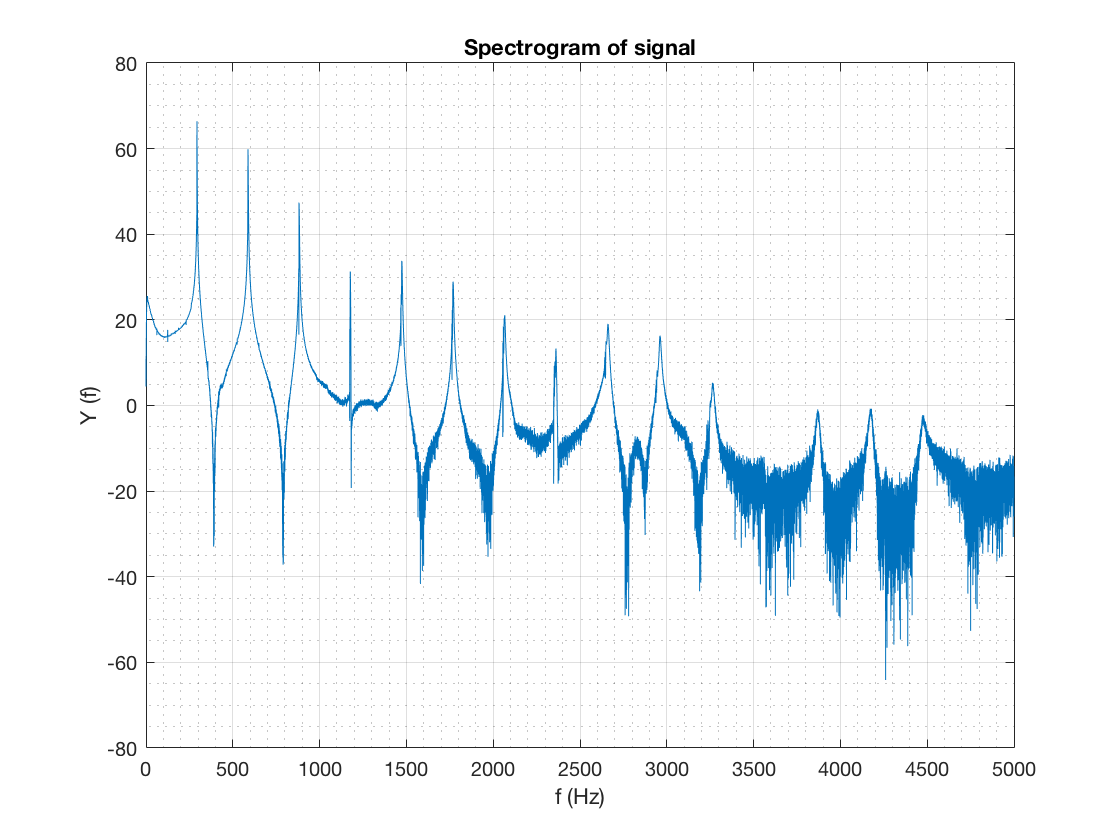

log_Y = 20*log10(Y);
plot_FFT(log_Y, Y_indices, Fs, 0, 5000);

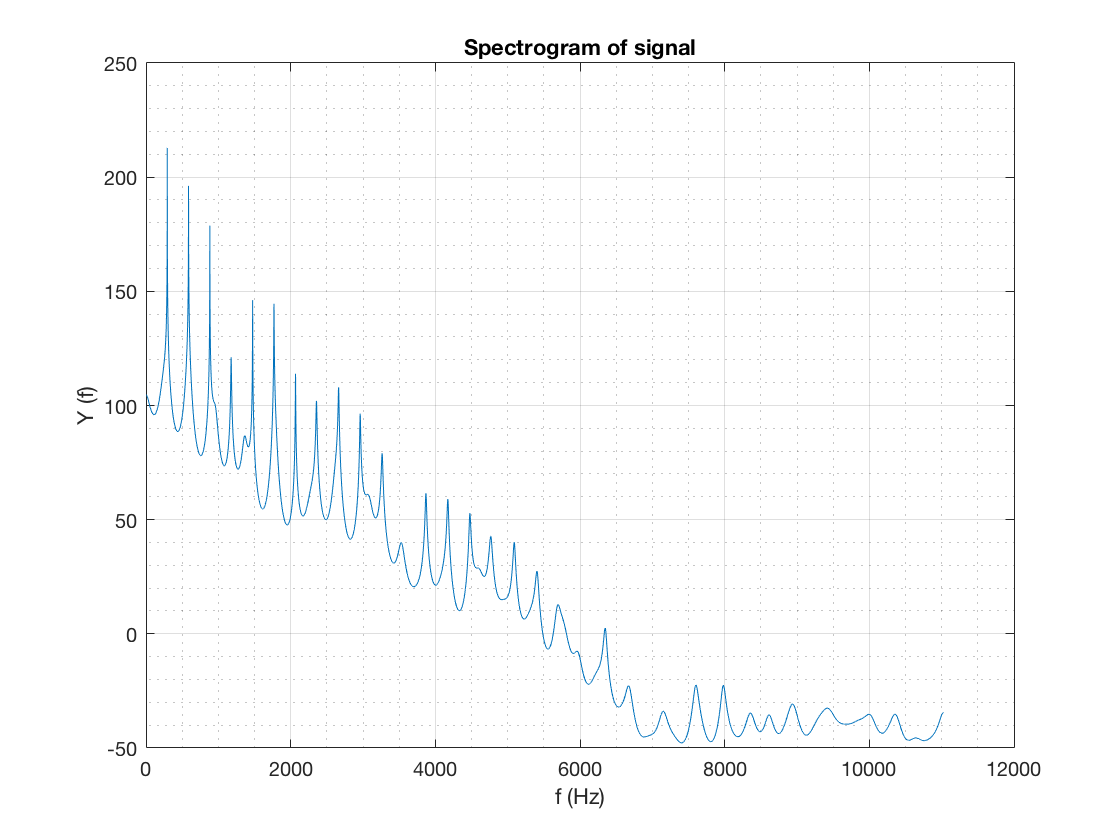

n_sins = 64;
nfft = 256;
S_resolution = 1;
[S,f,v,e] = m_music(signal(1:Fs), Fs, n_sins, nfft, S_resolution, 0, Fs/4);
log_S = 20*log10(S);
plot_pmusic(log_S, f);

% f_range = [292:0.01:300].';
% estimate_f = music_f(v, Fs, f_range);

Undefined function or variable 'f_range'.

% log_estimate_f = 20*log10(estimate_f);
% plot(f_range, log_estimate_f);

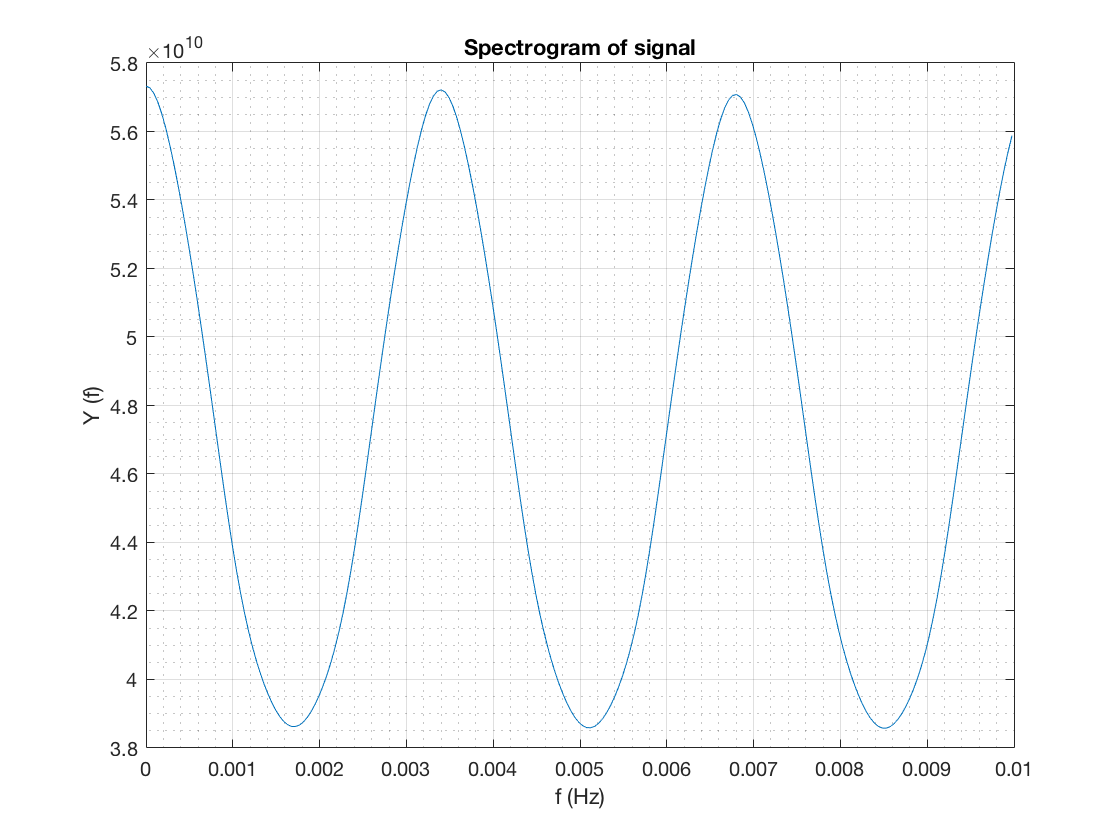

% frequency sampling of the fft : 1/n*Hz
fft_fs = 1/((Fs/2)/length(S));
[Y_fft, Y_fft_indices] = param_FFT(S, fft_fs);
plot_FFT(Y_fft, Y_fft_indices, fft_fs, 0, 0.01);

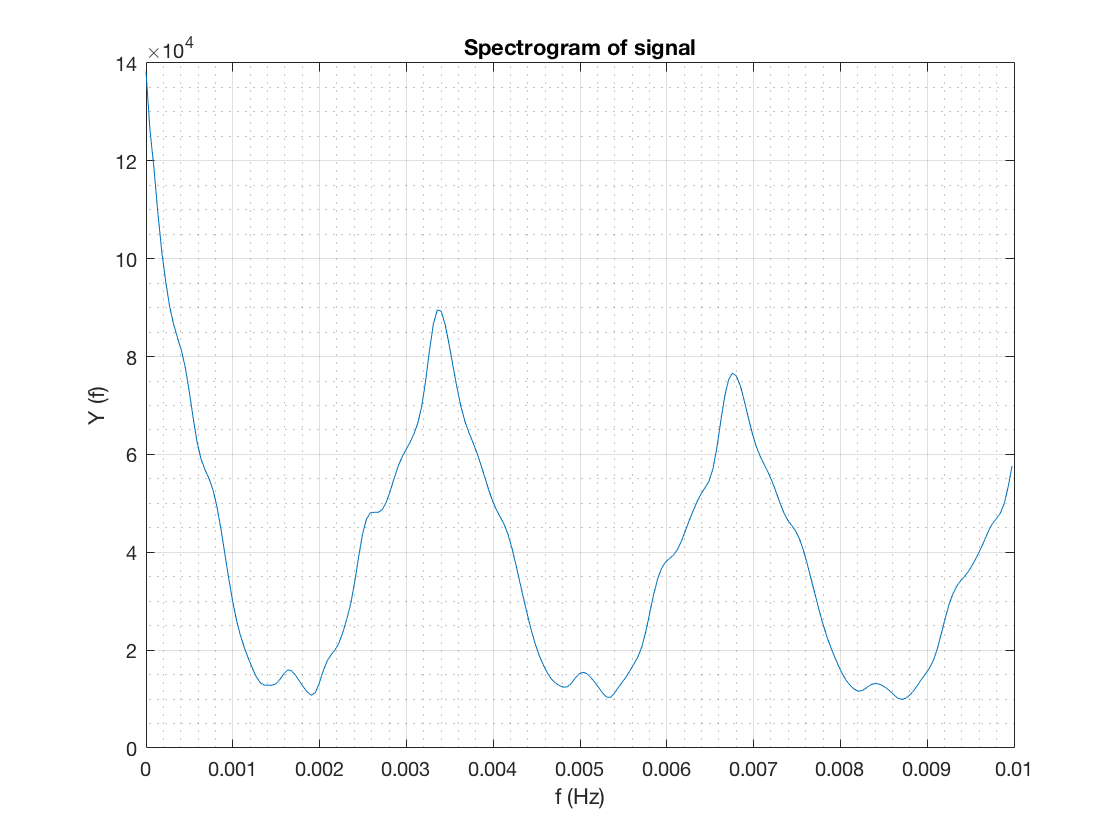

% fft_fs = 1/((Fs/2)/length(Y));
% [Y_fft, Y_fft_indices] = param_FFT(Y, fft_fs);
% plot_FFT(Y_fft, Y_fft_indices, fft_fs, 0, 0.01);

% Get the index of the period of Y_fft
index = find_peak_mod(Y_fft);
p = Y_fft_indices(index)

p = 0.0034

period = 1 / Y_fft_indices(index);

% how much ratio of side searching
n_partials = 10;
search_ratio = 8/9;
search_resolution = 0.00001;
n_points =100;

estimated_partials = ((1:n_partials) * period).';
found_partials = search_partials(v, Fs, period, estimated_partials, search_ratio, search_resolution, n_points);

it
it
it
it
it
it
it
it
it
it
it
it
it
it
it
it
it
it
it


[f_0, B] = least_square_pond(found_partials);